# Windowed-Sinc Filter

- y = sin(2*pi*f*t) / t

### Create the filter

sample_rate = 1000; % hz
t = -4:1/sample_rate:4;
num_points = length(t);

f = 8; % cutoff freq in hz
sinc_filter = sin(2*pi*f*t) ./ t;

% adjust for when t = 0 and normalize
sinc_filter(~isfinite(sinc_filter)) = max(sinc_filter);
sinc_filter = sinc_filter./sum(sinc_filter);

hz_vals = linspace(0, sample_rate/2, floor(num_points/2)+1);
power_sinc = abs(fft(sinc_filter));

### Window the filter

- use hann window [https://www.mathworks.com/help/signal/ref/hann.html](https://www.mathworks.com/help/signal/ref/hann.html)

- [https://en.wikipedia.org/wiki/Window_function](https://en.wikipedia.org/wiki/Window_function) 

windowed_sinc = sinc_filter .* hann(num_points)';
power_windowed = abs(fft(windowed_sinc));

### Plot the filters

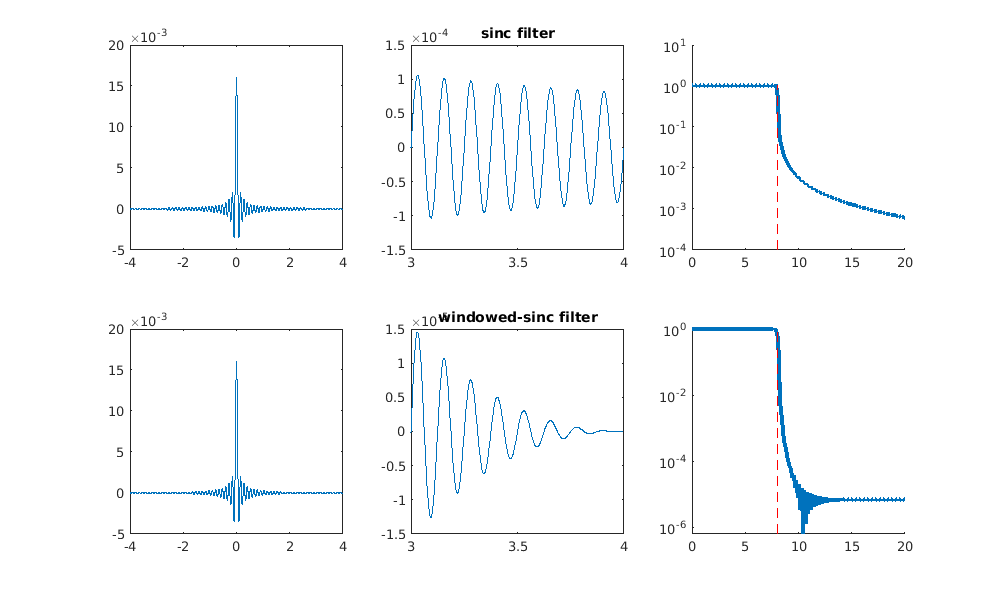

f1 = figure(1); clf;
f1.Position = [0 0 1000 600];

subplot(231);
plot(t, sinc_filter);

subplot(232);
plot(t, sinc_filter);
xlim([3 4]);
title("sinc filter");

subplot(233);
hold on;
plot(hz_vals, power_sinc(1:length(hz_vals)), 'linew', 3);
xlim([0 20]);
set(gca, 'YScale', 'log');
plot([1 1]*f, get(gca,'ylim'), 'r--'); % cutoff line
hold off;

subplot(234);
plot(t, windowed_sinc);

subplot(235);
plot(t, windowed_sinc);
xlim([3 4]);
title("windowed-sinc filter");

subplot(236);
hold on;
plot(hz_vals, power_windowed(1:length(hz_vals)), 'linew', 3);
xlim([0 20]);
set(gca, 'YScale', 'log');
plot([1 1]*f, get(gca,'ylim'), 'r--'); % cutoff line
hold off;